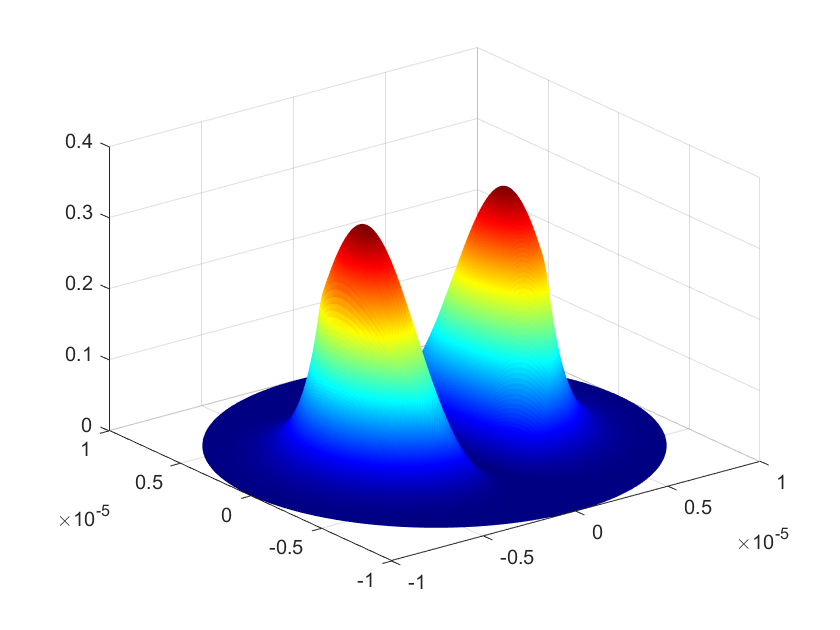

% Fiber parameters
a = 5e-6;           % Core radius (meters)
n1 = 1.45;          % Core refractive index
n2 = 1.44;          % Cladding refractive index
wavelength = 1.55e-6; % Wavelength (meters)
k0 = 2 * pi / wavelength; % Free-space wavenumber
V = 2 * pi * a / wavelength * sqrt(n1^2 - n2^2); % V-number

% Mode parameters
l = 1;              % Azimuthal mode number
m = 2;              % Radial mode number

% Solve for u and w (for simplicity, assume u is known for the mode)
u = 2.405;          % Example value for LP11 mode
w = sqrt(V^2 - u^2); % Cladding parameter

% Radial and azimuthal coordinates
r = linspace(0, 2 * a, 300); % Radial coordinate
phi = linspace(0, 2 * pi, 300); % Azimuthal coordinate
[R, Phi] = meshgrid(r, phi); % Create a grid for (r, phi)

% Field distribution in core and cladding
E_core = besselj(l, u * R / a) .* cos(l * Phi); % Core field
E_cladding = (besselj(l, u) / besselk(l, w)) * besselk(l, w * R / a) .* cos(l * Phi); % Cladding field
E = E_core; % Initialize field
E(R > a) = E_cladding(R > a); % Combine core and cladding fields

% Intensity (|E|^2)
I = abs(E).^2;

% Convert polar coordinates to Cartesian for plotting
[X, Y] = pol2cart(Phi, R);

% Plot the intensity
figure;
surf(X,Y,I, "EdgeColor","none")
colormap('jet')

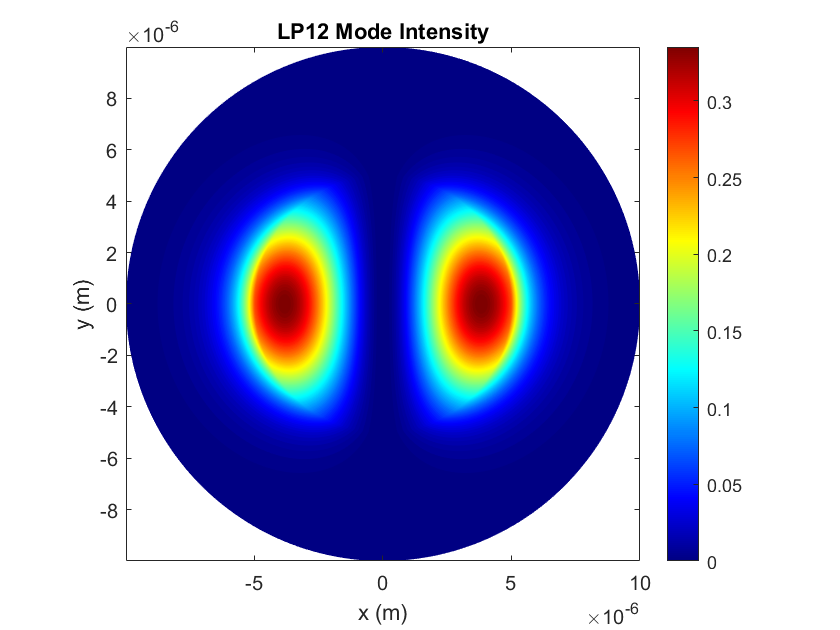

contourf(X, Y, I, 100, 'LineColor', 'none'); % Contour plot of intensity
colormap('jet');
colorbar;
title(['LP', num2str(l), num2str(m), ' Mode Intensity']);
xlabel('x (m)');
ylabel('y (m)');
axis equal;